clc;
clear;
%Geometry and Material Properties
L = 100; % Length in mm
width  = 10 % mm

width = 10

height = 10 % mm

height = 10

YoungsModulus = 2e5 % MPa or N/mm2

YoungsModulus = 200000

momentOfInteria = (width*(height^3))/12

momentOfInteria = 833.3333

EI = YoungsModulus*momentOfInteria

EI = 1.6667e+08



% Define domain and properties
x0 = 0;
xL = L;
f = -1;  % KN/m  or N/mm ( Negative downward direction )
a = EI;
elements = [1, 4, 10, 50,100]; % Array of different element counts

% Get the handle of the command window
commandwindow;

prompt_x0 = 'Enter the type of boundary condition at x0 (1. Fixed, 2. Roller/ Pin, 3. Free end): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        y0 = 0;  % Displacement at x0 is zero (Fixed end)
        theta0 = 0;  % Rotation at x0 is zero
    case 2
        y0  = 0;
        M0 = 0;  
    case 3
        % No boundary conditions to apply (Free end)
        % You can leave this section empty or add a comment like this.
    otherwise
        error('Invalid boundary condition type at x0');  % Handle invalid inputs
end


% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Fixed,2. Roller/ Pin, 3. Free end): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        yL = 0;  % Displacement at x0 is zero (Fixed end)
        thetaL = 0;  % Rotation at x0 is zero
    case 2
        yL = 0;
        ML = 0;  
    case 3
        % No boundary conditions to apply (Free end)
        % You can leave this section empty or add a comment like this.
    otherwise
        error('Invalid boundary condition type at xL');
end


% Prompt the user to input information about loads on the beam
prompt_load = 'Is there a load or moment present on the beam? (1. Point Load, 2. Moment, 3. Both, 4. None): ';
loadResponse = input(prompt_load);

switch loadResponse
    case 1  % Point Load
        P_val = input('Enter the value of the point load: ');
        P_loc = input('Enter the location of the point load: ');
        [P_index, is_on_node] = check_location(P_loc, 'Point Load', x0, xL, e);
        if is_on_node
            disp(['Point Load is at node index: ', num2str(P_index)]);
        end

        if isempty(P_index) % Check if the index is empty
            error('In the specified location Their is No node for load.');  
        end

    case 2  % Moment
        M_val = input('Enter the value of the moment: ');
        M_loc = input('Enter the location of the moment: ');
        [M_index, is_on_node] = check_location(M_loc, 'Moment', x0, xL, e);
        if is_on_node
            disp(['Moment is at node index: ', num2str(M_index)]);
        end
        if isempty(M_index) % Check if the index is empty
            error('In the specified location Their is No node for load.');  
        end

    case 3  % Both Point Load and Moment
        P_val1 = input('Enter the value of the point load: ');
        P_loc1 = input('Enter the location of the point load: ');
        M_val1 = input('Enter the value of the moment: ');
        M_loc1 = input('Enter the location of the moment: ');
        [indices, are_on_nodes] = check_both_locations(P_loc1, M_loc1, x0, xL, e);

        P_index1 = indices(1);
        M_index1 = indices(2);

        if are_on_nodes(1)
            disp(['Point Load is at node index: ', num2str(P_index1)]);
        end
        if are_on_nodes(2)
            disp(['Moment is at node index: ', num2str(M_index1)]);
        end

        if isempty(M_index) || isempty(P_index)
            error('In the specified location Their is No node for loads.');
        end

    case 4  % None
        disp('No load or moment present, continuing with the rest of the code.');

    otherwise
        error('Invalid response. Please enter a valid option (1-4).');
end

No load or moment present, continuing with the rest of the code.





% Initialize cell arrays for storing outputs
deflections = cell(length(elements), 1);
slopes = cell(length(elements), 1);
BMoments = cell(length(elements), 1);
SFs = cell(length(elements), 1);
Xs = cell(length(elements), 1);

% Loop over each element count
for idx = 1:length(elements)
    e = elements(idx);
    [K_global, Fv, total_DOF, X, DOF_element, DOF_node, h] = FEM_Beam_Processor(e, L, a, f);
    Gv = zeros(total_DOF, 1);
    
    if exist('P_index', 'var') && exist('P_loc', 'var') && exist('P_val', 'var')
        Gv((2*P_index)-1) = P_val;
    end
    
    if exist('M_index', 'var') && exist('M_loc', 'var') && exist('M_val', 'var')
        Gv( (2*M_index) ) = M_val;
    end
    
    if exist('P_index1', 'var') && exist('P_loc1', 'var') && exist('P_val1', 'var')
        Gv((2*P_index)-1) = P_val1;
    end
    
    if exist('M_index1', 'var') && exist('M_loc1', 'var') && exist('M_val1', 'var')
        Gv( (2*M_index1) ) = M_val1;
    end
    
    RHS = Fv + Gv;
    
    if exist('y0', 'var') && exist('theta0', 'var')
    
        K_global(1,:)= [1,zeros(1, total_DOF-1)];
        K_global(2,:)= [0,1,zeros(1, total_DOF-2)];
        
        RHS(1) = y0;
        RHS(2) = theta0;
    end
    
    if exist('y0', 'var') && exist('M0', 'var')
    
       K_global(1,:)= [1,zeros(1, total_DOF-1)];
       RHS(1) =M0;
    end
    
    if exist('yL', 'var') && exist('thetaL', 'var')
        K_global(end-1,:) = [zeros(1, total_DOF)];
        K_global(end-1, end-1) = 1;
    
        K_global(end,:)= [zeros(1, total_DOF-1),1];
        RHS(end-1) = yL;
        RHS(end) = thetaL;
    
    end
    
    if exist('yL', 'var') && exist('ML', 'var')
    
        K_global(end-1,:) = [zeros(1, total_DOF)];
        K_global(end-1, end-1) = 1;
    
        RHS(end-1) =ML;
    end
    
    
    UVUV = K_global\RHS;
    
    UV = columnVectorToMatrix(UVUV);
% Extract results
    deflections{idx} = UV(:,1);
    slopes{idx} = UV(:,2);
    Xs{idx} = X;
    
    %  calculateGeneralDerivative(u, h, derivativeOrder, forwardPoints, backwardPoints)
    Bmoment1 = calculateGeneralDerivative(slopes{idx}, h, 1, 4, 4);
    BMoments{idx} = -a * Bmoment1;
    
    %  calculateGeneralDerivative(u, h, derivativeOrder, forwardPoints, backwardPoints)
    SF1 = calculateGeneralDerivative(slopes{idx}, h, 2, 4, 4);
    SFs{idx} = a*SF1;
end

Number of points are very less for applying Second Derivative


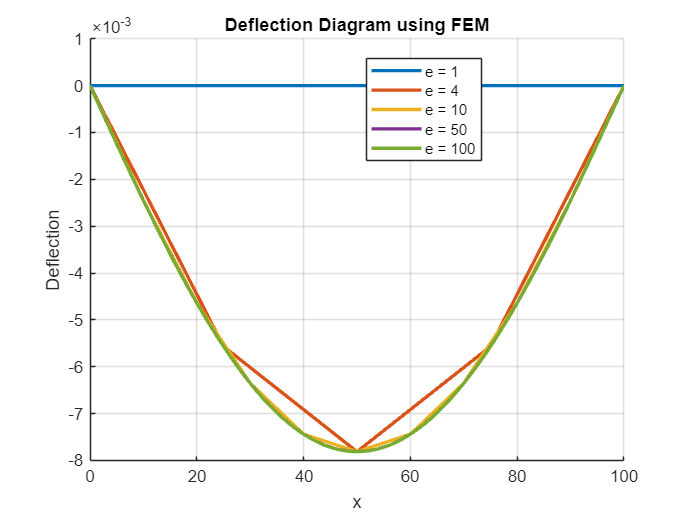


% Plotting results for all element configurations
figure;
hold on;
 % Colors for different element counts
for idx = 1:length(elements)
    plot(Xs{idx}, deflections{idx}, 'LineWidth', 2, 'DisplayName', sprintf('e = %d', elements(idx)));
    hold on;
end
xlabel('x');
ylabel('Deflection');
title('Deflection Diagram using FEM');
legend('Location', 'best');
grid on;
hold off;

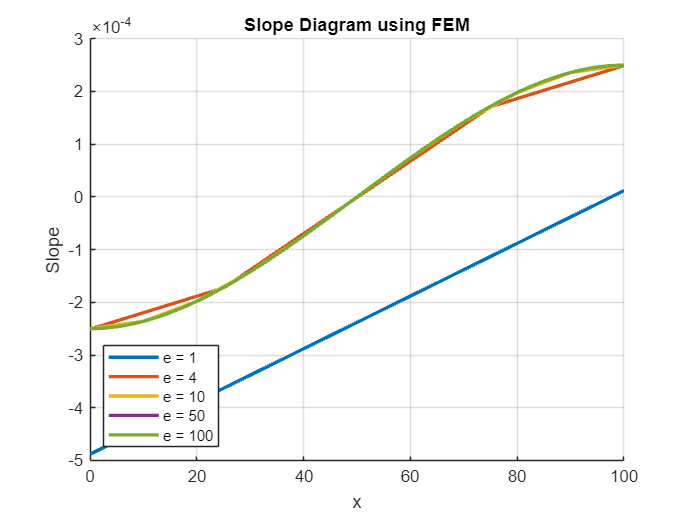


figure;
hold on;
for idx = 1:length(elements)
    plot(Xs{idx}, slopes{idx}, 'LineWidth', 2, 'DisplayName', sprintf('e = %d', elements(idx)));
end
xlabel('x');
ylabel('Slope');
title('Slope Diagram using FEM');
legend('Location', 'southwest');
grid on;
hold off;

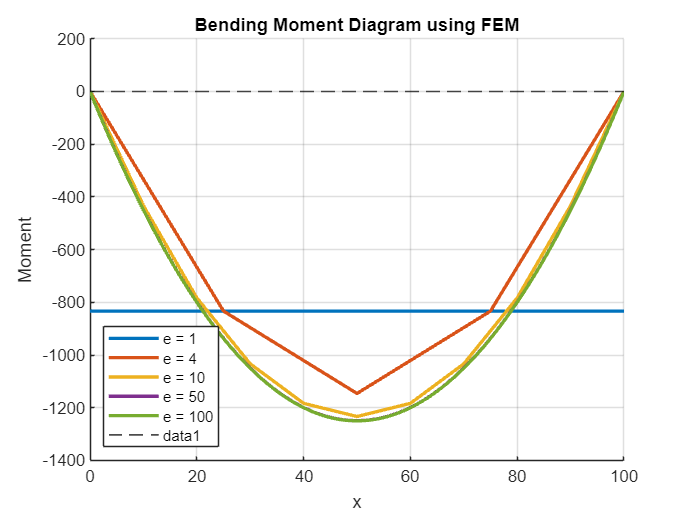


figure;
hold on;
for idx = 1:length(elements)
    plot(Xs{idx}, BMoments{idx}, 'LineWidth', 2, 'DisplayName', sprintf('e = %d', elements(idx)));
   
end
yline(0, 'k--', 'LineWidth', 1);
xlabel('x');
ylabel('Moment');
title('Bending Moment Diagram using FEM');
legend('Location', 'southwest');
grid on;
hold off;

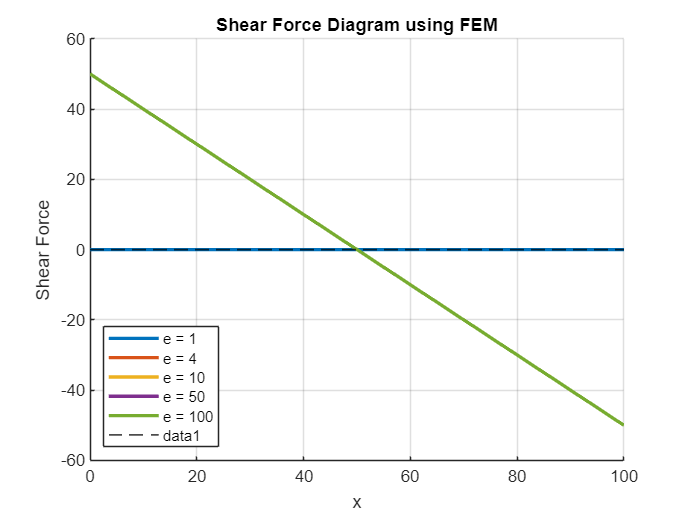


figure;
hold on;
for idx = 1:length(elements)
    plot(Xs{idx}, SFs{idx}, 'LineWidth', 2, 'DisplayName', sprintf('e = %d', elements(idx)));
 
end
yline(0, 'k--', 'LineWidth', 1);
xlabel('x');
ylabel('Shear Force');
title('Shear Force Diagram using FEM');
legend('Location', 'southwest');
grid on;
hold off;





% 
% % Calculate absolute maximums and minimums
% [max_abs_deflection, idx_max_def] = max(abs(deflection));
% [min_abs_deflection, idx_min_def] = min(abs(deflection));
% deflection_direction = 'Upward';
% if deflection(idx_max_def) < 0
%     deflection_direction = 'Downward';
% end
% 
% [max_abs_BMoment, idx_max_BM] = max(abs(BMoment));
% [min_abs_BMoment, idx_min_BM] = min(abs(BMoment));
% BMoment_direction = 'Tension top';
% if BMoment(idx_max_BM) < 0
%     BMoment_direction = 'Compression top';
% end
% [max_abs_SF, idx_max_SF] = max(abs(SF));
% [min_abs_SF, idx_min_SF] = min(abs(SF));
% SF_direction = 'Left';
% if SF(idx_max_SF) < 0
%     SF_direction = 'Right';
% end
% 
% % Extract corresponding X locations using indices
% X_max_def = X(idx_max_def);
% X_min_def = X(idx_min_def);
% 
% X_max_BM = X(idx_max_BM);
% X_min_BM = X(idx_min_BM);
% 
% X_max_SF = X(idx_max_SF);
% X_min_SF = X(idx_min_SF);
% 
% % Create and display the original table with unconverted units
% OriginalValues = round([max_abs_deflection; min_abs_deflection; max_abs_BMoment; min_abs_BMoment; max_abs_SF; min_abs_SF], 7);
% OriginalTable = table([X_max_def; X_min_def; X_max_BM; X_min_BM; X_max_SF; X_min_SF], ...
%                     OriginalValues, ...
%                     {deflection_direction; deflection_direction; BMoment_direction; BMoment_direction; SF_direction; SF_direction}, ...
%                     'VariableNames', {'Nodal_Location_mm', 'Value', 'Direction'}, ...
%                     'RowNames', {'Max Deflection (mm)', 'Min Deflection (mm)', 'Max Bending Moment (N-mm)', 'Min Bending Moment (N-mm)', 'Max Shear Force (N)', 'Min Shear Force (N)'});
% disp('Original Values Table (N, N-mm, mm):');
% disp(OriginalTable);
% 
% % Convert values for the second table
% ConvertedValues = round([max_abs_deflection; min_abs_deflection; max_abs_BMoment / 1000000; min_abs_BMoment / 1000000; max_abs_SF / 1000; min_abs_SF / 1000], 7);
% ConvertedTable = table([X_max_def / 1000; X_min_def / 1000; X_max_BM / 1000; X_min_BM / 1000; X_max_SF / 1000; X_min_SF / 1000], ...
%                     ConvertedValues, ...
%                     {deflection_direction; deflection_direction; BMoment_direction; BMoment_direction; SF_direction; SF_direction}, ...
%                     'VariableNames', {'Nodal_Location_Meters', 'Value', 'Direction'}, ...
%                     'RowNames', {'Max Deflection (m)', 'Min Deflection (m)', 'Max Bending Moment (KN-m)', 'Min Bending Moment (KN-m)', 'Max Shear Force (KN)', 'Min Shear Force (KN)'});
% disp('Converted Values Table (KN, KN-m, meters):');
% disp(ConvertedTable);
% 
